clear 

FileTable = [
% '01_01.mat';
% '01_02.mat';
%     '02_01.mat';
'03_01.mat';
'04_01.mat';
'05_01.mat';
% '07_01.mat';
'08_01.mat';
'09_01.mat';
%     '10_01.mat';
%     '12_01.mat';
% '13_01.mat';
% '14_01.mat';
'15_01.mat';
% '17_01.mat';
% '18_01.mat';
  '19_01.mat';
%     '20_01.mat';
% '21_01.mat';
% '22_01.mat';
'23_01.mat';
% '24_01.mat';
% '25_01.mat';
% '26_01.mat';
% '27_01.mat';
% '28_01.mat';
% '28_02.mat';
% '29_01.mat';
'30_01.mat';
% '32_01.mat';
% '33_01.mat';
'34_01.mat';
'35_01.mat';
];
Nfile = size(FileTable,1); 
DirName = './W203_4';

Distance.org = nan;
Distance.h = nan;
% AnalysisData = zeros(Nfile*Ntype,Nvalue);
 
for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    distanceFilter = AnalysisCdf(DirName,FileName);
    Distance.org = [Distance.org;distanceFilter.org];
    Distance.h = [Distance.h;distanceFilter.h];
end

ans = 18

ans = 83

ans = 28

ans = 130

ans = 136

ans = 110

ans = 143

ans = 119

ans = 163

ans = 128

ans = 106

ans = 107

ans = 103

ans = 107

ans = 46

ans = 43

ans = 12

ans = 57

ans = 36

ans = 64

ans = 49

ans = 57

length(Distance.org)

ans = 841

length(Distance.h)

ans = 1006

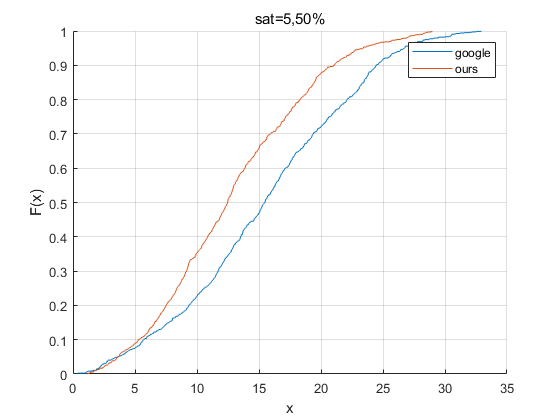

figure
hold on
cdfplot(Distance.org)
cdfplot(Distance.h)
legend('google','ours')
title('sat=5,50%')
hold off